load("test1Data.mat")
figureWidth = 12; % cm (max. 15)
figureRatio = 0.4; % height to width ratio
set(groot, 'defaultTextInterpreter', 'latex')
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
RGB = rgb2hex(orderedcolors("gem"));

figure, clf, hold on
yyaxis left
plot(rawTime, rawThrust)
yyaxis right
plot(rawTime, rawThrottle, "--")
ylim([0 100])
hold off

[thrust,time] = resample(rawThrust, rawTime, 80);

throttle = zeros(length(time),1);
throttle(1:234) = 20;
throttle(235:395) = 40;
throttle(396:554) = 60;
throttle(555:714) = 80;
throttle(715:875) = 100;
throttle(876:1035) = 80;
throttle(1036:1194) = 60;
throttle(1195:1354) = 40;
throttle(1355:1514) = 20;
throttle(1515:11104) = 40;
throttle(11105:11264) = 20;
throttle(11265:11424) = 40;
throttle(11425:11584) = 60;
throttle(11585:11744) = 80;
throttle(11745:11904) = 100;
throttle(11905:12064) = 80;
throttle(12065:12223) = 60;
throttle(12224:12383) = 40;
throttle(12384:end) = 20;

figure, clf, hold on
yyaxis left
plot(rawTime, rawThrust)
yyaxis right
plot(rawTime, rawThrottle, "--")
plot(time, throttle, "--")
ylim([0 100])
hold off

figure, clf, hold on
yyaxis left
plot(thrust)
yyaxis right
plot(throttle)
hold off

% 20-40
data = iddata(thrust(200:300)-thrust(200),throttle(200:300)-throttle(200),1/80)

data = Time domain data set with 101 samples.
Sample time: 0.0125 seconds           
                                      
Outputs      Unit (if specified)      
   y1                                 
                                      
Inputs       Unit (if specified)      
   u1                                 
                                      
Data Properties

C20_40 = procest(data,'P1D')


C20_40 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 6.1971                  
       Tp1 = 0.029167                
        Td = 0.04445                 
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 98.03%                     
FPE: 1.464, MSE: 1.379                             
 
Model Properties


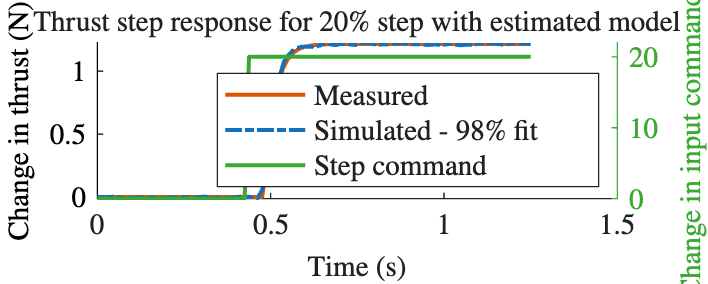

figure, clf, hold on
colororder([rgb2hex([0 0 0]),RGB(5)])
[y, ~, ~] = compare(C20_40,data);
yyaxis left
plot(time(200:300)-time(200), y.OutputData*9.81/1000, '-','Color',RGB(2))
plot(time(200:300)-time(200), data.OutputData*9.81/1000, '-.', 'Color',RGB(1))
ylabel('Change in thrust (N)')
yyaxis right
plot(time(200:300)-time(200),throttle(200:300)-throttle(200), 'Color',RGB(5))
ylabel('Change in input command (\%)')
ylim([0 22])

xlabel('Time (s)')
title('Thrust step response for 20\% step with estimated model')
legend('Measured', 'Simulated - 98\% fit\ \ ', 'Step command', 'Location','southeast')
set(findall(gcf, 'Type', 'Line'), 'LineWidth', 1.5);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off


% 40-60
data = iddata(thrust(360:460)-thrust(360),throttle(360:460)-throttle(360),1/80);
C40_60 = procest(data,'P1D')
compare(C40_60,data);

% 60-80
data = iddata(thrust(520:620)-thrust(520),throttle(520:620)-throttle(520),1/80);
C60_80 = procest(data,'P1D')
compare(C60_80,data);

% 80-100
data = iddata(thrust(680:780)-thrust(680),throttle(680:780)-throttle(680),1/80);
C80_100 = procest(data,'P1D')
compare(C80_100,data);

% 100-80
data = iddata(thrust(840:940)-thrust(840),throttle(840:940)-throttle(840),1/80);
C100_80 = procest(data,'P1D')
compare(C100_80,data);

% 80-60
data = iddata(thrust(1000:1100)-thrust(1000),throttle(1000:1100)-throttle(1000),1/80);
C80_60 = procest(data,'P1D')
compare(C80_60,data);

% 60-40
data = iddata(thrust(1160:1260)-thrust(1160),throttle(1160:1260)-throttle(1160),1/80);
C60_40 = procest(data,'P1D')
compare(C60_40,data);

% 40-20
data = iddata(thrust(1320:1420)-thrust(1320),throttle(1320:1420)-throttle(1320),1/80);
C40_20 = procest(data,'P1D')
compare(C40_20,data);

% HOT

% 20-40
data = iddata(thrust(11230:11330)-thrust(11230),throttle(11230:11330)-throttle(11230),1/80);
H20_40 = procest(data,'P1D')
compare(H20_40,data);

% 40-60
data = iddata(thrust(11400:11500)-thrust(11400),throttle(11400:11500)-throttle(11400),1/80);
H40_60 = procest(data,'P1D')
compare(H40_60,data);

% 60-80 HOT
data = iddata(thrust(11560:11660)-thrust(11560),throttle(11560:11660)-throttle(11560),1/80);
H60_80 = procest(data,'P1D')
compare(H60_80,data);

% 80-100 HOT
data = iddata(thrust(11720:11820)-thrust(11720),throttle(11720:11820)-throttle(11720),1/80);
H80_100 = procest(data,'P1D')
compare(H80_100,data);

% 100-80
data = iddata(thrust(11880:11980)-thrust(11880),throttle(11880:11980)-throttle(11880),1/80);
H100_80 = procest(data,'P1D')
compare(H100_80,data);

% 80-60 HOT
data = iddata(thrust(12030:12130)-thrust(12030),throttle(12030:12130)-throttle(12030),1/80);
H80_60 = procest(data,'P1D')
compare(H80_60,data);

% 60-40 HOT
data = iddata(thrust(12190:12290)-thrust(12190),throttle(12190:12290)-throttle(12190),1/80);
H60_40 = procest(data,'P1D')
compare(H60_40,data);

% 40-20 HOT
data = iddata(thrust(12350:12450)-thrust(12350),throttle(12350:12450)-throttle(12350),1/80);
H40_20 = procest(data,'P1D')
compare(H40_20,data);

Kp_c_1 = [C20_40.Kp C40_20.Kp C40_60.Kp C60_40.Kp C60_80.Kp C80_60.Kp C80_100.Kp C100_80.Kp];
Kp_h_1 = [H20_40.Kp H40_20.Kp H40_60.Kp H60_40.Kp H60_80.Kp H80_60.Kp H80_100.Kp H100_80.Kp];

array2table([Kp_c_1;Kp_h_1],"VariableNames",{'20-40', '40-20', '40-60', '60-40', '60-80', '80-60', '80-100', '100-80'}, "RowNames", {'Cold', 'Hot'})

Tp_c_1 = [C20_40.Tp1 C40_20.Tp1 C40_60.Tp1 C60_40.Tp1 C60_80.Tp1 C80_60.Tp1 C80_100.Tp1 C100_80.Tp1];
Tp_h_1 = [H20_40.Tp1 H40_20.Tp1 H40_60.Tp1 H60_40.Tp1 H60_80.Tp1 H80_60.Tp1 H80_100.Tp1 H100_80.Tp1];

array2table([Tp_c_1;Tp_h_1],"VariableNames",{'20-40', '40-20', '40-60', '60-40', '60-80', '80-60', '80-100', '100-80'}, "RowNames", {'Cold', 'Hot'})

Td_c_1 = [C20_40.Td C40_20.Td C40_60.Td C60_40.Td C60_80.Td C80_60.Td C80_100.Td C100_80.Td];
Td_h_1 = [H20_40.Td H40_20.Td H40_60.Td H60_40.Td H60_80.Td H80_60.Td H80_100.Td H100_80.Td];

array2table([Td_c_1; Td_h_1],"VariableNames",{'20-40', '40-20', '40-60', '60-40', '60-80', '80-60', '80-100', '100-80'}, "RowNames", {'Cold', 'Hot'})